%% =========================================================================
%  NED UNIVERSITY OF ENGINEERING & TECHNOLOGY - KARACHI
%  OPEN ENDED LAB
%  POWER SYSTEM ANALYSIS — EE-362
%  TOPIC: ASYMMETRICAL FAULT ANALYSIS ON MATLAB
%  DEPARTMENT OF ELECTRICAL ENGINEERING
%  MUHAMMAD TAHA EE-23319
%  SECTION D
%  BATCH 2023
%% =========================================================================

clc; clear; close all;
format short g;

fprintf('=================================================================\n');

fprintf('   IEEE 9-BUS POWER SYSTEM — FAULT ANALYSIS v4.1\n');

   IEEE 9-BUS POWER SYSTEM — FAULT ANALYSIS v4.1


fprintf('   100 MVA Base | Symmetrical Component Method\n');

   100 MVA Base | Symmetrical Component Method


fprintf('   All v4.0 Issues Corrected\n');

   All v4.0 Issues Corrected


fprintf('=================================================================\n\n');


%% =========================================================================
%  SECTION 1: SYSTEM DATA
%% =========================================================================

% ----- Base quantities -----
Sbase_MVA = 100;

% Nominal voltages at each bus (kV):
%   Buses 1,2,3 = generator terminals (LV side of transformers)
%   Buses 4-9   = 230 kV transmission network
Vbase_kV = [16.5, 18.0, 13.8, 230, 230, 230, 230, 230, 230];

% Base current per bus: Ibase = Sbase / (sqrt(3) * Vbase)  [kA]
Ibase_kA = Sbase_MVA ./ (sqrt(3) .* Vbase_kV);

Vzone_kV = Vbase_kV;   % identical to Vbase_kV for this system

% ----- Generator subtransient reactances (positive-sequence, pu) -----
Xd1 = 0.0608;
Xd2 = 0.1198;
Xd3 = 0.1813;

% ----- Generator negative-sequence reactances (pu) -----
% Round-rotor assumption: X2 ≈ Xd''
Xg1_neg = 0.0608;
Xg2_neg = 0.1198;
Xg3_neg = 0.1813;

% ----- Generator zero-sequence reactances (pu) -----
% X0 ≠ Xd''; determined by winding geometry.
% Typical: X0 ≈ 0.5–0.7 × Xd''
Zn1 = 0.10;
Zn2 = 0.15;
Zn3 = 0.18;

Xg1_zero = 0.06;
Xg2_zero = 0.10;
Xg3_zero = 0.12;

% ----- Transformer leakage reactances (pu) -----
% [FIX-D] T1: Bus1(Delta-LV) — Bus4(Yg-HV)  16.5/230 kV
%         T2: Bus2(Delta-LV) — Bus7(Yg-HV)  18/230 kV
%         T3: Bus3(Delta-LV) — Bus9(Yg-HV)  13.8/230 kV
% Transformer resistance is negligible for fault studies (X/R >> 1)
XT1 = 0.0576;
XT2 = 0.0625;
XT3 = 0.0586;

% ----- [FIX-A] Transmission line COMPLEX impedances (R + jX, pu) -----
% Both R and X are now carried into Ybus construction.
R45 = 0.0100;  X45 = 0.1008;
R46 = 0.0085;  X46 = 0.0720;
R57 = 0.0170;  X57 = 0.1610;
R69 = 0.0072;  X69 = 0.0850;
R78 = 0.0130;  X78 = 0.1280;
R89 = 0.0115;  X89 = 0.1190;

% Complex positive/negative sequence branch impedances
Z45 = R45 + 1j*X45;
Z46 = R46 + 1j*X46;
Z57 = R57 + 1j*X57;
Z69 = R69 + 1j*X69;
Z78 = R78 + 1j*X78;
Z89 = R89 + 1j*X89;

% ----- [FIX-A] Zero-sequence line impedances -----
% Carson's approximation: X0 ≈ 3*X1, R0 ≈ 3*R1 (earth-return resistance)
% Using scalar 3× factor for both R and X components.
Z45_0 = 3*R45 + 1j*3*X45;
Z46_0 = 3*R46 + 1j*3*X46;
Z57_0 = 3*R57 + 1j*3*X57;
Z69_0 = 3*R69 + 1j*3*X69;
Z78_0 = 3*R78 + 1j*3*X78;
Z89_0 = 3*R89 + 1j*3*X89;

% ----- [NEW-6] Network-relative ground stub -----
% X_stub = 1e6 × max zero-seq line reactance.
X_stub = 1e6 * max(imag([Z45_0, Z46_0, Z57_0, Z69_0, Z78_0, Z89_0]));

nBus = 9;

% ----- [NEW-10] Fault impedance sweep -----
Zf_cases  = [0.00, 0.01, 0.05];
Zf_labels = {'Bolted (Zf=0)', 'Light arc (Zf=0.01pu)', 'Heavy arc (Zf=0.05pu)'};

Vf = 1.0;   % Uniform pre-fault voltage (pu)

fprintf('System parameters loaded.\n');

System parameters loaded.


fprintf('  Generators  : 3  (Buses 1,2,3 — solidly grounded)\n');

  Generators  : 3  (Buses 1,2,3 — solidly grounded)


fprintf('  Transformers: 3  (Delta-LV / Yg-HV: T1:1-4, T2:2-7, T3:3-9)\n');

  Transformers: 3  (Delta-LV / Yg-HV: T1:1-4, T2:2-7, T3:3-9)


fprintf('  Lines       : 6  (4-5, 4-6, 5-7, 6-9, 7-8, 8-9)\n');

  Lines       : 6  (4-5, 4-6, 5-7, 6-9, 7-8, 8-9)


fprintf('  Fault cases : %d  (Zf = %s pu)\n\n', ...
        length(Zf_cases), num2str(Zf_cases));

  Fault cases : 3  (Zf = 0        0.01        0.05 pu)




%% =========================================================================
%  SECTION 2–4: BUILD SEQUENCE YBUS MATRICES
%  [FIX-A] All three Ybus builders now use complex Z = R+jX branches.
%% =========================================================================
fprintf('Building sequence admittance matrices...\n');

Building sequence admittance matrices...



Ybus1 = buildYbus_positive(nBus, Xd1,Xd2,Xd3, XT1,XT2,XT3, ...
                            Z45,Z46,Z57,Z69,Z78,Z89);

Ybus2 = buildYbus_negative(nBus, Xg1_neg,Xg2_neg,Xg3_neg, XT1,XT2,XT3, ...
                            Z45,Z46,Z57,Z69,Z78,Z89);

Ybus0 = buildYbus_zero(nBus, Xg1_zero,Xg2_zero,Xg3_zero, ...
                        Zn1,Zn2,Zn3, X_stub, ...
                        Z45_0,Z46_0,Z57_0,Z69_0,Z78_0,Z89_0);

fprintf('  Positive, Negative, Zero sequence Ybus: DONE\n');

  Positive, Negative, Zero sequence Ybus: DONE



%% =========================================================================
%  SECTION 5: COMPUTE Zbus (LU DECOMPOSITION)
%% =========================================================================
In    = eye(nBus);
Zbus1 = Ybus1 \ In;
Zbus2 = Ybus2 \ In;
Zbus0 = Ybus0 \ In;

fprintf('  Zbus matrices (LU decomposition): DONE\n\n');

  Zbus matrices (LU decomposition): DONE




%% =========================================================================
%  [NEW-5] SECTION 5b: CONDITION NUMBER CHECK — ZERO-SEQUENCE NETWORK
%% =========================================================================
cond0 = cond(Ybus0);
fprintf('Ybus0 condition number: %.3e\n', cond0);

Ybus0 condition number: 7.053e+06


if cond0 > 1e6
    fprintf(['  NOTE: Ybus0 is near-singular (cond > 1e6).\n' ...
             '  This is physically correct for Delta-LV/Yg-HV systems:\n' ...
             '  transmission buses 4-9 have no physical zero-sequence\n' ...
             '  ground path. Z0(k,k) >> Z1(k,k) for k=4..9, so SLG/DLG\n' ...
             '  currents at those buses are near-zero. Results are valid.\n\n']);
end

  NOTE: Ybus0 is near-singular (cond > 1e6).
  This is physically correct for Delta-LV/Yg-HV systems:
  transmission buses 4-9 have no physical zero-sequence
  ground path. Z0(k,k) >> Z1(k,k) for k=4..9, so SLG/DLG
  currents at those buses are near-zero. Results are valid.




fprintf('  Z0/Z1 ratio per bus (ratio >> 1 => SLG ≈ 0 at that bus):\n');

  Z0/Z1 ratio per bus (ratio >> 1 => SLG ≈ 0 at that bus):


for k = 1:nBus
    ratio = abs(Zbus0(k,k)) / abs(Zbus1(k,k));
    flag = '';
    if ratio > 100
        flag = '  <-- near-open zero-seq (expected for Delta-isolated buses)';
    end
    fprintf('    Bus %d: Z0/Z1 = %.2f%s\n', k, ratio, flag);
end

    Bus 1: Z0/Z1 = 6.19
    Bus 2: Z0/Z1 = 5.54
    Bus 3: Z0/Z1 = 5.49
    Bus 4: Z0/Z1 = 1069915.05  <-- near-open zero-seq (expected for Delta-isolated buses)
    Bus 5: Z0/Z1 = 663512.26  <-- near-open zero-seq (expected for Delta-isolated buses)
    Bus 6: Z0/Z1 = 781917.63  <-- near-open zero-seq (expected for Delta-isolated buses)
    Bus 7: Z0/Z1 = 824823.89  <-- near-open zero-seq (expected for Delta-isolated buses)
    Bus 8: Z0/Z1 = 609730.66  <-- near-open zero-seq (expected for Delta-isolated buses)
    Bus 9: Z0/Z1 = 814281.03  <-- near-open zero-seq (expected for Delta-isolated buses)


fprintf('\n');

%% =========================================================================
%  SECTION 5c: PRINT Zbus DIAGONAL TABLE
%% =========================================================================
printZbusTable(Zbus1, Zbus2, Zbus0, nBus);

  THEVENIN IMPEDANCES (Zbus Diagonals, pu)
  Bus |   Z1 (pos)           |   Z2 (neg)           |   Z0 (zero)
  ----|----------------------|----------------------|----------------------
    1 |  0.0004+j 0.0494 |  0.0004+j 0.0494 |  0.3000+j 0.0600
    2 |  0.0012+j 0.0832 |  0.0012+j 0.0832 |  0.4500+j 0.1000
    3 |  0.0019+j 0.1007 |  0.0019+j 0.1007 |  0.5400+j 0.1200
    4 |  0.0014+j 0.0752 |  0.0014+j 0.0752 |  0.0142+j80500.1367
    5 |  0.0066+j 0.1211 |  0.0066+j 0.1211 |  0.0176+j80500.1702
    6 |  0.0047+j 0.1028 |  0.0047+j 0.1028 |  0.0129+j80500.1288
    7 |  0.0028+j 0.0976 |  0.0028+j 0.0976 |  0.0199+j80500.1947
    8 |  0.0072+j 0.1318 |  0.0072+j 0.1318 |  0.0172+j80500.1755
    9 |  0.0033+j 0.0988 |  0.0033+j 0.0988 |  0.0138+j80500.1442




%% =========================================================================
%  SECTION 6: FAULT ANALYSIS — BOLTED CASE (Zf=0) AT ALL 9 BUSES
%% =========================================================================
Zf = 0;

I3ph_pu = zeros(1,nBus);  ISLG_pu = zeros(1,nBus);
ILL_pu  = zeros(1,nBus);  IDLG_pu = zeros(1,nBus);
IG_SLG  = zeros(1,nBus);  IG_DLG  = zeros(1,nBus);

results = struct();

fprintf('=================================================================\n');

fprintf('   FAULT ANALYSIS — BOLTED FAULTS AT ALL 9 BUSES\n');

   FAULT ANALYSIS — BOLTED FAULTS AT ALL 9 BUSES


fprintf('=================================================================\n\n');


for k = 1:nBus
    Z1 = Zbus1(k,k);
    Z2 = Zbus2(k,k);
    Z0 = Zbus0(k,k);

    % (a) THREE-PHASE
    [Ia3,Ib3,Ic3,I0_3,I1_3,I2_3] = fault_3phase(Vf,Z1,Zf);
    I3ph_pu(k) = abs(Ia3);

    % (b) SLG — Phase A to ground
    [Ia_slg,Ib_slg,Ic_slg,I0_slg,I1_slg,I2_slg] = fault_SLG(Vf,Z0,Z1,Z2,Zf);
    ISLG_pu(k) = abs(Ia_slg);
    IG_SLG(k)  = 3 * abs(I0_slg);

    % (c) LL — Phase B to C
    [Ia_ll,Ib_ll,Ic_ll,I0_ll,I1_ll,I2_ll] = fault_LL(Vf,Z1,Z2,Zf);
    ILL_pu(k) = abs(Ib_ll);

    % (d) DLG — Phase B and C to ground
    [Ia_dlg,Ib_dlg,Ic_dlg,I0_dlg,I1_dlg,I2_dlg] = fault_DLG(Vf,Z0,Z1,Z2,Zf);
    IDLG_pu(k) = abs(Ib_dlg);
    IG_DLG(k)  = 3 * abs(I0_dlg);

    % [NEW-12] Boundary condition self-validation
    validateBoundaryConditions(k, Ia_slg,Ib_slg,Ic_slg, ...
                                  Ia_ll, Ib_ll, Ic_ll,  ...
                                  Ia_dlg);

    % Store full phasor results
    results(k).bus    = k;
    results(k).Z1     = Z1;  results(k).Z2 = Z2;  results(k).Z0 = Z0;
    results(k).Ia3    = Ia3;    results(k).Ib3    = Ib3;    results(k).Ic3    = Ic3;
    results(k).I0_3   = I0_3;   results(k).I1_3   = I1_3;   results(k).I2_3   = I2_3;
    results(k).Ia_slg = Ia_slg; results(k).Ib_slg = Ib_slg; results(k).Ic_slg = Ic_slg;
    results(k).I0_slg = I0_slg; results(k).I1_slg = I1_slg; results(k).I2_slg = I2_slg;
    results(k).Ia_ll  = Ia_ll;  results(k).Ib_ll  = Ib_ll;  results(k).Ic_ll  = Ic_ll;
    results(k).I0_ll  = I0_ll;  results(k).I1_ll  = I1_ll;  results(k).I2_ll  = I2_ll;
    results(k).Ia_dlg = Ia_dlg; results(k).Ib_dlg = Ib_dlg; results(k).Ic_dlg = Ic_dlg;
    results(k).I0_dlg = I0_dlg; results(k).I1_dlg = I1_dlg; results(k).I2_dlg = I2_dlg;
end

%% =========================================================================
%  SECTION 7: PRINT FAULT SUMMARY — pu AND kA
%% =========================================================================
printFaultSummaryTable(results, nBus, Ibase_kA);

  FAULT CURRENT MAGNITUDES — Bolted Faults
  Bus |  3-Phase           |   SLG              |    LL              |   DLG
       |  (pu)    (kA)     |  (pu)    (kA)     |  (pu)    (kA)     |  (pu)    (kA)
  -----|---------------------|---------------------|---------------------|---------------------
    1 | 20.2360  70.8077 | 8.8212  30.8663 | 17.5249  61.3213 | 19.8456  69.4416
    2 | 12.0176  38.5464 | 5.7137  18.3267 | 10.4075  33.3821 | 11.9256  38.2513
    3 | 9.9271  41.5321 | 4.7492  19.8694 | 8.5971  35.9678 | 9.8598  41.2505
    4 | 13.2908   3.3363 | 0.0000   0.0000 | 11.5102   2.8893 | 11.5102   2.8893
    5 | 8.2424   2.0690 | 0.0000   0.0000 | 7.1381   1.7918 | 7.1381   1.7918
    6 | 9.7132   2.4382 | 0.0000   0.0000 | 8.4119   2.1116 | 8.4119   2.1116
    7 | 10.2462   2.5720 | 0.0000   0.0000 | 8.8735   2.2274 | 8.8735   2.2274
    8 | 7.574


%% =========================================================================
%  [NEW-4] SECTION 7b: GROUND CURRENT TABLE (SLG and DLG)
%% =========================================================================
printGroundCurrentTable(IG_SLG, IG_DLG, nBus, Ibase_kA);

  GROUND CURRENTS Ig = 3|I0| — SLG and DLG Faults
  (Current seen by 51G ground overcurrent and 67G relays)
  Bus |    SLG Ig           |    DLG Ig
       |  (pu)    (kA)      |  (pu)    (kA)
  -----|---------------------|--------------------
    1 | 8.8212  30.8663  | 4.8092  16.8278
    2 | 5.7137  18.3267  | 3.1757  10.1861
    3 | 4.7492  19.8694  | 2.6449  11.0653
    4 | 0.0000   0.0000  | 0.0000   0.0000
    5 | 0.0000   0.0000  | 0.0000   0.0000
    6 | 0.0000   0.0000  | 0.0000   0.0000
    7 | 0.0000   0.0000  | 0.0000   0.0000
    8 | 0.0000   0.0000  | 0.0000   0.0000
    9 | 0.0000   0.0000  | 0.0000   0.0000




%% =========================================================================
%  [FIX-A][NEW-9] SECTION 7c: X/R RATIO AND DC OFFSET — NOW CORRECT
%  Ybus1 now includes line resistances, so Zbus1 diagonals have real parts.
%% =========================================================================
printDCOffsetTable(Zbus1, nBus, I3ph_pu, Ibase_kA);

  X/R RATIO AND ASYMMETRICAL FAULT CURRENT (Breaker Duty)
  Based on: i_peak = sqrt(2)*Isym*(1+exp(-pi*R/X))
  [FIX-A: Ybus1 now includes line resistances — X/R values correct]
  Bus |  R1(pu)  |  X1(pu)  |  X/R   | Ipeak_asym (kA) | Isym_3ph (kA)
  ----|----------|----------|--------|-----------------|---------------
    1 |  0.00036 |  0.04942 | 137.07 |        198.0053 |       70.8077
    2 |  0.00122 |  0.08320 |  67.93 |        106.5617 |       38.5464
    3 |  0.00189 |  0.10072 |  53.25 |        114.1055 |       41.5321
    4 |  0.00137 |  0.07523 |  55.02 |          9.1746 |        3.3363
    5 |  0.00660 |  0.12114 |  18.35 |          5.3917 |        2.0690
    6 |  0.00474 |  0.10284 |  21.68 |          6.4311 |        2.4382
    7 |  0.00284 |  0.09756 |  34.39 |          6.9573 |        2.5720
    8 |  0.00716 |  0.13183 |  18.40 |          4.9


%% =========================================================================
%  SECTION 8: BUS VOLTAGES DURING FAULT — ALL FOUR FAULT TYPES [NEW-2]
%% =========================================================================
for busV = [1 4 7]
    fprintf('\n=================================================================\n');
    fprintf('  BUS VOLTAGES DURING FAULT AT BUS %d\n', busV);
    fprintf('=================================================================\n');
    computeBusVoltages_all(busV, Zbus1,Zbus2,Zbus0, nBus, Vf, Zf);
end

  BUS VOLTAGES DURING FAULT AT BUS 1



  [3-Phase fault at Bus 1 — Bus Voltage Profile]
  Bus | Va (pu)             | Vb (pu)             | Vc (pu)
  ----|---------------------|---------------------|---------------------
    1 | 0.0000∠   0.00°   | 0.0000∠-120.00°   | 0.0000∠ 120.00°
    2 | 0.2344∠-177.32°   | 0.2344∠  62.68°   | 0.2344∠ -57.32°
    3 | 0.3326∠-178.24°   | 0.3326∠  61.76°   | 0.3326∠ -58.24°
    4 | 0.7819∠ 179.38°   | 0.7819∠  59.38°   | 0.7819∠ -60.62°
    5 | 0.6180∠-179.95°   | 0.6180∠  60.05°   | 0.6180∠ -59.95°
    6 | 0.6249∠-179.60°   | 0.6249∠  60.40°   | 0.6249∠ -59.60°
    7 | 0.3567∠-177.32°   | 0.3567∠  62.68°   | 0.3567∠ -57.32°
    8 | 0.3999∠-177.86°   | 0.3999∠  62.14°   | 0.3999∠ -57.86°
    9 | 0.4401∠-178.24°   | 0.4401∠  61.76°   | 0.4401∠ -58.24°

  [SLG fault at Bus 1 — Bus Voltage Profile]
  Bus | Va (pu)             | Vb (pu)             | Vc (pu)
  ----|---------------------|---------------------|---------------------
    1 | 0.0000∠  38.66°   | 1.3805∠-159.56°   | 1.7989∠ 135.98

  BUS VOLTAGES DURING FAULT AT BUS 4



  [3-Phase fault at Bus 4 — Bus Voltage Profile]
  Bus | Va (pu)             | Vb (pu)             | Vc (pu)
  ----|---------------------|---------------------|---------------------
    1 | 0.5135∠ 180.00°   | 0.5135∠  60.00°   | 0.5135∠ -60.00°
    2 | 0.2998∠-176.70°   | 0.2998∠  63.30°   | 0.2998∠ -56.70°
    3 | 0.4254∠-177.62°   | 0.4254∠  62.38°   | 0.4254∠ -57.62°
    4 | 0.0000∠   0.00°   | 0.0000∠-120.00°   | 0.0000∠ 120.00°
    5 | 0.7904∠-179.33°   | 0.7904∠  60.67°   | 0.7904∠ -59.33°
    6 | 0.7993∠-178.97°   | 0.7993∠  61.03°   | 0.7993∠ -58.97°
    7 | 0.4562∠-176.70°   | 0.4562∠  63.30°   | 0.4562∠ -56.70°
    8 | 0.5115∠-177.24°   | 0.5115∠  62.76°   | 0.5115∠ -57.24°
    9 | 0.5629∠-177.62°   | 0.5629∠  62.38°   | 0.5629∠ -57.62°

  [SLG fault at Bus 4 — Bus Voltage Profile]
  Bus | Va (pu)             | Vb (pu)             | Vc (pu)
  ----|---------------------|---------------------|---------------------
    1 | 0.0000∠ 178.96°   | 0.0000∠  -1.04°   | 0.0000∠  -1.04

  BUS VOLTAGES DURING FAULT AT BUS 7



  [3-Phase fault at Bus 7 — Bus Voltage Profile]
  Bus | Va (pu)             | Vb (pu)             | Vc (pu)
  ----|---------------------|---------------------|---------------------
    1 | 0.1806∠-176.08°   | 0.1806∠  63.92°   | 0.1806∠ -56.08°
    2 | 0.6572∠ 180.00°   | 0.6572∠  60.00°   | 0.6572∠ -60.00°
    3 | 0.3255∠-176.98°   | 0.3255∠  63.02°   | 0.3255∠ -56.98°
    4 | 0.3517∠-176.08°   | 0.3517∠  63.92°   | 0.3517∠ -56.08°
    5 | 0.6009∠-178.50°   | 0.6009∠  61.50°   | 0.6009∠ -58.50°
    6 | 0.3879∠-176.63°   | 0.3879∠  63.37°   | 0.3879∠ -56.63°
    7 | 0.0000∠   0.00°   | 0.0000∠   0.00°   | 0.0000∠   0.00°
    8 | 0.7048∠-178.99°   | 0.7048∠  61.01°   | 0.7048∠ -58.99°
    9 | 0.4307∠-176.98°   | 0.4307∠  63.02°   | 0.4307∠ -56.98°

  [SLG fault at Bus 7 — Bus Voltage Profile]
  Bus | Va (pu)             | Vb (pu)             | Vc (pu)
  ----|---------------------|---------------------|---------------------
    1 | 0.0000∠-177.74°   | 0.0000∠   2.26°   | 0.0000∠   2.26


%% =========================================================================
%  [FIX-C][NEW-3] SECTION 8b: BRANCH FAULT CURRENT CONTRIBUTIONS
%  Now prints correct kA using per-branch voltage-zone Ibase.
%% =========================================================================
fprintf('\n=================================================================\n');

fprintf('  BRANCH FAULT CURRENT CONTRIBUTIONS — 3-Phase fault\n');

  BRANCH FAULT CURRENT CONTRIBUTIONS — 3-Phase fault


fprintf('=================================================================\n');


% Branch table: [from-bus, to-bus, R(pu), X(pu), HV-zone-bus]
% HV-zone-bus: the bus whose Vbase_kV defines the branch's current base.
% For transformer branches the HV (transmission) side is used because the
% Zbus is referenced to the system pu base, which is the 230 kV zone.
% For transmission line branches both end-buses are the same voltage zone.
branches = [1 4 real(1j*XT1) XT1  4;   % T1 — use 230 kV zone (HV side)
            2 7 real(1j*XT2) XT2  7;   % T2
            3 9 real(1j*XT3) XT3  9;   % T3
            4 5 R45 X45  4;
            4 6 R46 X46  4;
            5 7 R57 X57  5;
            6 9 R69 X69  6;
            7 8 R78 X78  7;
            8 9 R89 X89  8];
% Column 5 is the reference bus for Ibase lookup.
% Transformer columns 3 (R) are zero because transformers are modelled
% as purely reactive; the complex Z is 0 + j*XT, which is correct.

computeBranchFaultCurrents(branches, Zbus1, nBus, Vf, Zf, Ibase_kA);


  3-Phase fault — branch current magnitudes
  Columns = faulted bus; Rows = branch (from->to)

  Branch        Bus1    Bus2    Bus3    Bus4    Bus5    Bus6    Bus7    Bus8    Bus9  
  ----------  ---------------------------------------------------------------
   1 ->  4 pu 13.5738 2.2895 2.6836 8.9152 4.1401 4.9336 2.9704 2.4619 3.6183
   2 ->  7 pu 1.9566 12.3323 1.7300 2.5025 2.6518 2.0174 10.5145 2.8578 2.3326
   3 ->  9 pu 1.8345 1.3839 12.6566 2.3464 1.4510 2.7638 1.7955 2.2563 12.8964
   4 ->  5 pu 1.6196 1.9023 0.0090 7.8033 4.8392 0.8238 2.4681 0.8741 0.0121
   4 ->  6 pu 2.1714 0.3872 2.6925 11.0246 0.9040 8.0570 0.5024 1.5878 3.6303
   5 ->  7 pu 1.6196 1.9023 0.0090 2.0715 2.9860 0.8238 3.7120 0.8741 0.0121
   6 ->  9 pu 2.1714 0.3872 2.6925 2.7773 0.9040 7.7726 0.5024 1.5878 8.0944
   7 ->  8 pu 0.3370 1.7710 1.7211 0.4311 0.5470 1.1939 5.4777 4.0493 2.3205
   8 ->  9 pu 0.3370 1.7710 1.7211 0.4311 0.5470 1.1939 2.2977 4.5275 6.0464

  Branch        Bus1    Bus2    Bus3   


%% =========================================================================
%  [FIX-E][NEW-10] SECTION 8c: FAULT IMPEDANCE SWEEP
%  Local variable renamed Zf_val to avoid outer-scope shadowing.
%% =========================================================================
fprintf('\n=================================================================\n');

fprintf('  FAULT IMPEDANCE SWEEP — SLG fault, Bus 7\n');

  FAULT IMPEDANCE SWEEP — SLG fault, Bus 7


fprintf('=================================================================\n');

faultImpedanceSweep(7, Zbus0,Zbus1,Zbus2, Vf, Zf_cases, Zf_labels, Ibase_kA);

  SLG fault at Bus 7 — effect of fault impedance:

  Fault condition              | I_SLG (pu) | I_SLG (kA) | Reduction
  ----------------------------|------------|------------|----------
  Bolted (Zf=0)                |     0.0000 |     0.0000 |    0.00%
  Light arc (Zf=0.01pu)        |     0.0000 |     0.0000 |    0.00%
  Heavy arc (Zf=0.05pu)        |     0.0000 |     0.0000 |    0.00%

  Minimum relay pickup must detect the heavy arc case (Zf=0.05 pu).




%% =========================================================================
%  SECTION 9: VALIDATION — FULL HIERARCHY I3ph>=IDLG>=ILL>=ISLG
%% =========================================================================
fprintf('\n=================================================================\n');

fprintf('  VALIDATION: Fault Current Hierarchy\n');

  VALIDATION: Fault Current Hierarchy


fprintf('=================================================================\n');

validateFaultHierarchy(I3ph_pu, ISLG_pu, ILL_pu, IDLG_pu, nBus);

  Bus | 3ph>=DLG | 3ph>=LL | 3ph>=SLG | DLG>=LL | LL>=SLG
  ----|----------|---------|----------|---------|--------
    1 |     OK   |    OK   |     OK   |    OK   |    OK  
    2 |     OK   |    OK   |     OK   |    OK   |    OK  
    3 |     OK   |    OK   |     OK   |    OK   |    OK  
    4 |     OK   |    OK   |     OK   |    OK   |    OK  
    5 |     OK   |    OK   |     OK   |    OK   |    OK  
    6 |     OK   |    OK   |     OK   |    OK   |    OK  
    7 |     OK   |    OK   |     OK   |    OK   |    OK  
    8 |     OK   |    OK   |     OK   |    OK   |    OK  
    9 |     OK   |    OK   |     OK   |    OK   |    OK  

  PASSED: Full hierarchy I3ph >= IDLG >= ILL >= ISLG at all buses.


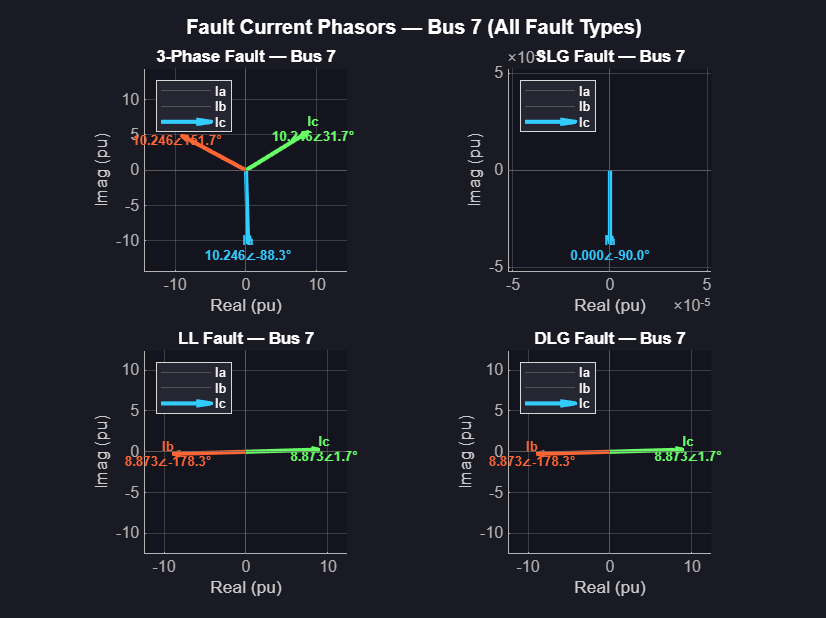


%% =========================================================================
%  SECTION 10: PHASOR DIAGRAMS — Bus 7, All Fault Types
%% =========================================================================
plotPhasorDiagrams(results, 7);

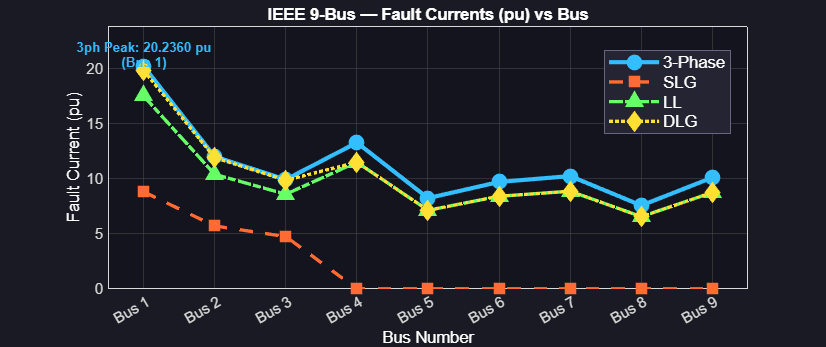

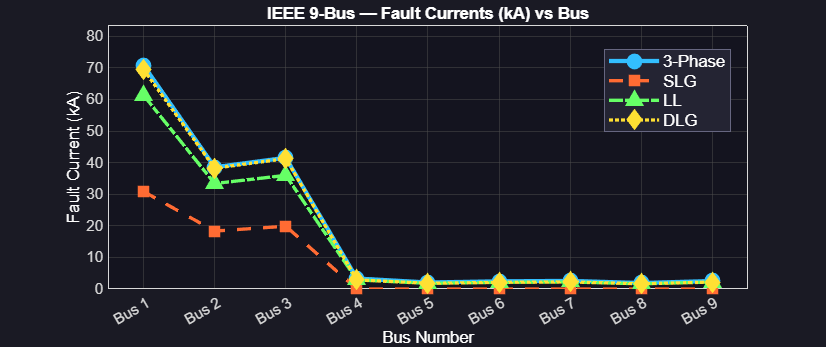

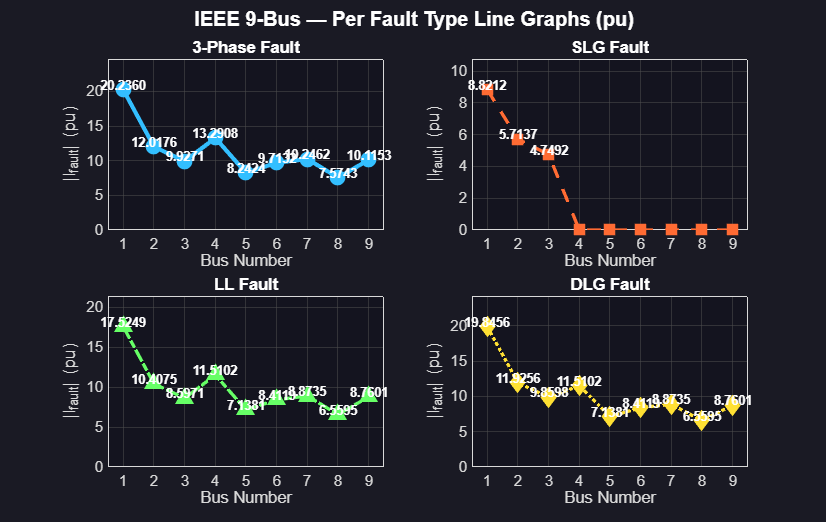


%% =========================================================================
%  [FIX-B] SECTION 11: LINE GRAPHS — Fault Currents (pu and kA)
%  ylim in ALL figures now uses max of all four fault-type arrays.
%% =========================================================================
plotFaultCurrentLines(I3ph_pu, ISLG_pu, ILL_pu, IDLG_pu, ...
                      I3ph_pu.*Ibase_kA, ISLG_pu.*Ibase_kA, ...
                      ILL_pu.*Ibase_kA,  IDLG_pu.*Ibase_kA, nBus);

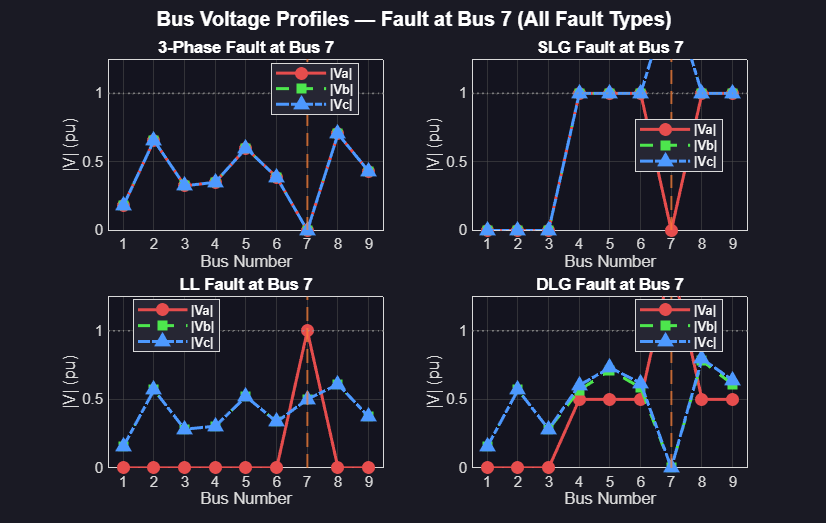


%% =========================================================================
%  SECTION 12: VOLTAGE PROFILE LINE GRAPH — All fault types, Bus 7 fault
%% =========================================================================
plotVoltageProfiles(7, Zbus1,Zbus2,Zbus0, nBus, Vf, Zf);


fprintf('\n=================================================================\n');

fprintf('  SIMULATION COMPLETE\n');

  SIMULATION COMPLETE


fprintf('=================================================================\n');



%% =========================================================================
%%                      FUNCTION DEFINITIONS
%% =========================================================================

%% ---- SHARED HELPER: addBranch ----
function Ybus = addBranch(Ybus, i, j, Z)
    % Add branch admittance 1/Z between bus i and bus j.
    % j = 0  =>  shunt to reference (ground).
    % Z may be purely imaginary (1j*X) or complex (R+1j*X).
    % [NEW-11] Guard against zero or near-zero impedance.
    if abs(Z) < 1e-12
        error('addBranch: impedance Z at bus %d is zero or near-zero. Check data.', i);
    end
    y = 1 / Z;
    Ybus(i,i) = Ybus(i,i) + y;
    if j ~= 0
        Ybus(j,j) = Ybus(j,j) + y;
        Ybus(i,j) = Ybus(i,j) - y;
        Ybus(j,i) = Ybus(j,i) - y;
    end
end

%% ---- BUILD POSITIVE-SEQUENCE Ybus ----
% [FIX-A] Line branches use complex Z = R+jX (was purely jX in v4.0).
% Generator and transformer branches remain purely reactive (R << X).
function Ybus = buildYbus_positive(n, Xd1,Xd2,Xd3, XT1,XT2,XT3, ...
                                    Z45,Z46,Z57,Z69,Z78,Z89)
    Ybus = zeros(n,n);
    % Generator subtransient shunts to reference
    Ybus = addBranch(Ybus,1,0, 1j*Xd1);
    Ybus = addBranch(Ybus,2,0, 1j*Xd2);
    Ybus = addBranch(Ybus,3,0, 1j*Xd3);
    % Transformer series branches (purely reactive — R negligible)
    Ybus = addBranch(Ybus,1,4, 1j*XT1);
    Ybus = addBranch(Ybus,2,7, 1j*XT2);
    Ybus = addBranch(Ybus,3,9, 1j*XT3);
    % Transmission lines — complex impedance
    Ybus = addBranch(Ybus,4,5, Z45);
    Ybus = addBranch(Ybus,4,6, Z46);
    Ybus = addBranch(Ybus,5,7, Z57);
    Ybus = addBranch(Ybus,6,9, Z69);
    Ybus = addBranch(Ybus,7,8, Z78);
    Ybus = addBranch(Ybus,8,9, Z89);
end

%% ---- BUILD NEGATIVE-SEQUENCE Ybus ----
% [FIX-A] Identical topology to positive-sequence; uses X2 for generators.
function Ybus = buildYbus_negative(n, Xg1,Xg2,Xg3, XT1,XT2,XT3, ...
                                    Z45,Z46,Z57,Z69,Z78,Z89)
    Ybus = zeros(n,n);
    Ybus = addBranch(Ybus,1,0, 1j*Xg1);
    Ybus = addBranch(Ybus,2,0, 1j*Xg2);
    Ybus = addBranch(Ybus,3,0, 1j*Xg3);
    Ybus = addBranch(Ybus,1,4, 1j*XT1);
    Ybus = addBranch(Ybus,2,7, 1j*XT2);
    Ybus = addBranch(Ybus,3,9, 1j*XT3);
    Ybus = addBranch(Ybus,4,5, Z45);
    Ybus = addBranch(Ybus,4,6, Z46);
    Ybus = addBranch(Ybus,5,7, Z57);
    Ybus = addBranch(Ybus,6,9, Z69);
    Ybus = addBranch(Ybus,7,8, Z78);
    Ybus = addBranch(Ybus,8,9, Z89);
end

%% ---- BUILD ZERO-SEQUENCE Ybus ----
function Ybus = buildYbus_zero(n, Xg1,Xg2,Xg3, Zn1,Zn2,Zn3, X_stub, ...
                                Z45_0,Z46_0,Z57_0,Z69_0,Z78_0,Z89_0)
    Ybus = zeros(n,n);

    % Generator zero-seq shunts with neutral impedance [NEW-7]
    Z0_gen1 = 1j*Xg1 + 3*Zn1;
    Z0_gen2 = 1j*Xg2 + 3*Zn2;
    Z0_gen3 = 1j*Xg3 + 3*Zn3;
    Ybus(1,1) = Ybus(1,1) + 1/Z0_gen1;
    Ybus(2,2) = Ybus(2,2) + 1/Z0_gen2;
    Ybus(3,3) = Ybus(3,3) + 1/Z0_gen3;

    % Transformer series branches: OMITTED — Delta blocks zero-sequence.

    % Transmission line zero-sequence admittances (complex Z0) [FIX-A]
    Ybus = addBranch(Ybus,4,5, Z45_0);
    Ybus = addBranch(Ybus,4,6, Z46_0);
    Ybus = addBranch(Ybus,5,7, Z57_0);
    Ybus = addBranch(Ybus,6,9, Z69_0);
    Ybus = addBranch(Ybus,7,8, Z78_0);
    Ybus = addBranch(Ybus,8,9, Z89_0);

    % High-impedance ground stubs at transmission buses [NEW-6]
    for bus = 4:n
        Ybus(bus,bus) = Ybus(bus,bus) + 1/(1j*X_stub);
    end
end

%% ---- THREE-PHASE FAULT ----
function [Ia,Ib,Ic,I0,I1,I2] = fault_3phase(Vf,Z1,Zf)
    % Only positive-sequence network active.
    % I1 = Vf/(Z1+Zf),  I2=I0=0
    a  = exp(1j*2*pi/3);
    I1 = Vf / (Z1 + Zf);
    I2 = 0;  I0 = 0;
    Ia = I1;
    Ib = a^2 * I1;
    Ic = a   * I1;
end

%% ---- SLG FAULT — Phase A to ground ----
function [Ia,Ib,Ic,I0,I1,I2] = fault_SLG(Vf,Z0,Z1,Z2,Zf)
    % All three sequence networks in SERIES.
    % I1=I2=I0=Vf/(Z1+Z2+Z0+3Zf),  Ia=3I1, Ib≈0, Ic≈0
    a  = exp(1j*2*pi/3);
    I1 = Vf / (Z1 + Z2 + Z0 + 3*Zf);
    I2 = I1;  I0 = I1;
    Ia = I0 + I1       + I2;
    Ib = I0 + a^2*I1   + a*I2;
    Ic = I0 + a*I1     + a^2*I2;
end

%% ---- LL FAULT — Phase B to C ----
function [Ia,Ib,Ic,I0,I1,I2] = fault_LL(Vf,Z1,Z2,Zf)
    % Positive and negative sequence anti-phase. I0=0.
    % I1=Vf/(Z1+Z2+Zf), I2=-I1
    a  = exp(1j*2*pi/3);
    I1 = Vf / (Z1 + Z2 + Zf);
    I2 = -I1;  I0 = 0;
    Ia = I0 + I1       + I2;
    Ib = I0 + a^2*I1   + a*I2;
    Ic = I0 + a*I1     + a^2*I2;
end

%% ---- DLG FAULT — Phase B and C to ground ----
function [Ia,Ib,Ic,I0,I1,I2] = fault_DLG(Vf,Z0,Z1,Z2,Zf)
    % Z_par = Z2 || (Z0+3Zf); I1=Vf/(Z1+Z_par)
    % I2=-I1*(Z0+3Zf)/(Z2+Z0+3Zf); I0=-I1*Z2/(Z2+Z0+3Zf)
    a  = exp(1j*2*pi/3);
    denom = Z2 + Z0 + 3*Zf;
    if abs(denom) < 1e-12
        error('fault_DLG: Z2+Z0+3Zf is zero — unphysical impedance combination.');
    end
    Z_par = (Z2 * (Z0 + 3*Zf)) / denom;
    I1 = Vf / (Z1 + Z_par);
    I2 = -I1 * (Z0 + 3*Zf) / denom;
    I0 = -I1 * Z2           / denom;
    Ia = I0 + I1       + I2;
    Ib = I0 + a^2*I1   + a*I2;
    Ic = I0 + a*I1     + a^2*I2;
end

%% ---- [NEW-12] BOUNDARY CONDITION SELF-VALIDATION ----
function validateBoundaryConditions(k, Ia_slg,Ib_slg,Ic_slg, ...
                                       Ia_ll,Ib_ll,Ic_ll,Ia_dlg)
    tol = 1e-8;
    if abs(Ib_slg) > tol || abs(Ic_slg) > tol
        fprintf('  [WARN] Bus %d SLG: Ib or Ic not zero (|Ib|=%.2e, |Ic|=%.2e)\n', ...
                k, abs(Ib_slg), abs(Ic_slg));
    end
    if abs(Ia_ll) > tol
        fprintf('  [WARN] Bus %d LL: Ia not zero (|Ia|=%.2e)\n', k, abs(Ia_ll));
    end
    if abs(Ia_dlg) > tol
        fprintf('  [WARN] Bus %d DLG: Ia not zero (|Ia|=%.2e)\n', k, abs(Ia_dlg));
    end
end

%% ---- PRINT Zbus DIAGONAL TABLE ----
function printZbusTable(Zbus1,Zbus2,Zbus0,n)
    fprintf('=================================================================\n');
    fprintf('  THEVENIN IMPEDANCES (Zbus Diagonals, pu)\n');
    fprintf('=================================================================\n');
    fprintf('  Bus |   Z1 (pos)           |   Z2 (neg)           |   Z0 (zero)\n');
    fprintf('  ----|----------------------|----------------------|----------------------\n');
    for k = 1:n
        z1=Zbus1(k,k); z2=Zbus2(k,k); z0=Zbus0(k,k);
        fprintf('   %2d | %7.4f+j%7.4f | %7.4f+j%7.4f | %7.4f+j%7.4f\n', ...
            k, real(z1),imag(z1), real(z2),imag(z2), real(z0),imag(z0));
    end
    fprintf('\n');
end

%% ---- PRINT FAULT SUMMARY TABLE — pu AND kA ----
function printFaultSummaryTable(results, n, Ibase_kA)
    fprintf('=================================================================\n');
    fprintf('  FAULT CURRENT MAGNITUDES — Bolted Faults\n');
    fprintf('=================================================================\n');
    fprintf('  Bus |  3-Phase           |   SLG              |    LL              |   DLG\n');
    fprintf('       |  (pu)    (kA)     |  (pu)    (kA)     |  (pu)    (kA)     |  (pu)    (kA)\n');
    fprintf('  -----|---------------------|---------------------|---------------------|---------------------\n');
    for k = 1:n
        r = results(k);
        I3  = abs(r.Ia3);
        Slg = abs(r.Ia_slg);
        Ll  = abs(r.Ib_ll);
        Dlg = abs(r.Ib_dlg);
        fprintf('   %2d | %6.4f  %7.4f | %6.4f  %7.4f | %6.4f  %7.4f | %6.4f  %7.4f\n', ...
            k, I3,  I3*Ibase_kA(k), ...
               Slg, Slg*Ibase_kA(k), ...
               Ll,  Ll*Ibase_kA(k), ...
               Dlg, Dlg*Ibase_kA(k));
    end
    fprintf('\n');

    fprintf('=================================================================\n');
    fprintf('  DETAILED SEQUENCE CURRENTS — BUS-BY-BUS\n');
    fprintf('=================================================================\n');
    for k = 1:n
        r = results(k);
        fprintf('\n  --- BUS %d (Ibase = %.4f kA) ---\n', k, Ibase_kA(k));
        fprintf('  Z1=%7.4f+j%7.4f  Z2=%7.4f+j%7.4f  Z0=%7.4f+j%7.4f\n', ...
            real(r.Z1),imag(r.Z1), real(r.Z2),imag(r.Z2), real(r.Z0),imag(r.Z0));

        fprintf('\n  [3-Phase Fault]\n');
        fprintf('    I0=%6.4f∠%6.1f°  I1=%6.4f∠%6.1f°  I2=%6.4f∠%6.1f°\n', ...
            abs(r.I0_3),angle(r.I0_3)*180/pi, ...
            abs(r.I1_3),angle(r.I1_3)*180/pi, ...
            abs(r.I2_3),angle(r.I2_3)*180/pi);
        fprintf('    Ia=%6.4f∠%6.1f° (%6.4f kA)  Ib=%6.4f∠%6.1f°  Ic=%6.4f∠%6.1f°\n', ...
            abs(r.Ia3),angle(r.Ia3)*180/pi, abs(r.Ia3)*Ibase_kA(k), ...
            abs(r.Ib3),angle(r.Ib3)*180/pi, abs(r.Ic3),angle(r.Ic3)*180/pi);

        fprintf('\n  [SLG Fault — Phase A to Ground]\n');
        fprintf('    I0=%6.4f∠%6.1f°  I1=%6.4f∠%6.1f°  I2=%6.4f∠%6.1f°\n', ...
            abs(r.I0_slg),angle(r.I0_slg)*180/pi, ...
            abs(r.I1_slg),angle(r.I1_slg)*180/pi, ...
            abs(r.I2_slg),angle(r.I2_slg)*180/pi);
        fprintf('    Ia=%6.4f∠%6.1f° (%6.4f kA)  Ib=%6.4f∠%6.1f°  Ic=%6.4f∠%6.1f°\n', ...
            abs(r.Ia_slg),angle(r.Ia_slg)*180/pi, abs(r.Ia_slg)*Ibase_kA(k), ...
            abs(r.Ib_slg),angle(r.Ib_slg)*180/pi, abs(r.Ic_slg),angle(r.Ic_slg)*180/pi);
        fprintf('    Ground current Ig = 3|I0| = %6.4f pu (%6.4f kA)\n', ...
            3*abs(r.I0_slg), 3*abs(r.I0_slg)*Ibase_kA(k));

        fprintf('\n  [LL Fault — Phase B to C]\n');
        fprintf('    I0=%6.4f∠%6.1f°  I1=%6.4f∠%6.1f°  I2=%6.4f∠%6.1f°\n', ...
            abs(r.I0_ll),angle(r.I0_ll)*180/pi, ...
            abs(r.I1_ll),angle(r.I1_ll)*180/pi, ...
            abs(r.I2_ll),angle(r.I2_ll)*180/pi);
        fprintf('    Ia=%6.4f∠%6.1f°  Ib=%6.4f∠%6.1f° (%6.4f kA)  Ic=%6.4f∠%6.1f°\n', ...
            abs(r.Ia_ll),angle(r.Ia_ll)*180/pi, ...
            abs(r.Ib_ll),angle(r.Ib_ll)*180/pi, abs(r.Ib_ll)*Ibase_kA(k), ...
            abs(r.Ic_ll),angle(r.Ic_ll)*180/pi);

        fprintf('\n  [DLG Fault — Phase B,C to Ground]\n');
        fprintf('    I0=%6.4f∠%6.1f°  I1=%6.4f∠%6.1f°  I2=%6.4f∠%6.1f°\n', ...
            abs(r.I0_dlg),angle(r.I0_dlg)*180/pi, ...
            abs(r.I1_dlg),angle(r.I1_dlg)*180/pi, ...
            abs(r.I2_dlg),angle(r.I2_dlg)*180/pi);
        fprintf('    Ia=%6.4f∠%6.1f°  Ib=%6.4f∠%6.1f° (%6.4f kA)  Ic=%6.4f∠%6.1f°\n', ...
            abs(r.Ia_dlg),angle(r.Ia_dlg)*180/pi, ...
            abs(r.Ib_dlg),angle(r.Ib_dlg)*180/pi, abs(r.Ib_dlg)*Ibase_kA(k), ...
            abs(r.Ic_dlg),angle(r.Ic_dlg)*180/pi);
        fprintf('    Ground current Ig = 3|I0| = %6.4f pu (%6.4f kA)\n', ...
            3*abs(r.I0_dlg), 3*abs(r.I0_dlg)*Ibase_kA(k));
    end
end

%% ---- [NEW-4] PRINT GROUND CURRENT TABLE ----
function printGroundCurrentTable(IG_SLG, IG_DLG, n, Ibase_kA)
    fprintf('=================================================================\n');
    fprintf('  GROUND CURRENTS Ig = 3|I0| — SLG and DLG Faults\n');
    fprintf('  (Current seen by 51G ground overcurrent and 67G relays)\n');
    fprintf('=================================================================\n');
    fprintf('  Bus |    SLG Ig           |    DLG Ig\n');
    fprintf('       |  (pu)    (kA)      |  (pu)    (kA)\n');
    fprintf('  -----|---------------------|--------------------\n');
    for k = 1:n
        fprintf('   %2d | %6.4f  %7.4f  | %6.4f  %7.4f\n', ...
            k, IG_SLG(k), IG_SLG(k)*Ibase_kA(k), ...
               IG_DLG(k), IG_DLG(k)*Ibase_kA(k));
    end
    fprintf('\n');
end

%% ---- [FIX-A][NEW-9] X/R RATIO AND DC OFFSET TABLE ----
% Now uses complex Zbus1 (R+jX line impedances included) for accurate X/R.
function printDCOffsetTable(Zbus1, n, I3ph_pu, Ibase_kA)
    fprintf('=================================================================\n');
    fprintf('  X/R RATIO AND ASYMMETRICAL FAULT CURRENT (Breaker Duty)\n');
    fprintf('  Based on: i_peak = sqrt(2)*Isym*(1+exp(-pi*R/X))\n');
    fprintf('  [FIX-A: Ybus1 now includes line resistances — X/R values correct]\n');
    fprintf('=================================================================\n');
    fprintf('  Bus |  R1(pu)  |  X1(pu)  |  X/R   | Ipeak_asym (kA) | Isym_3ph (kA)\n');
    fprintf('  ----|----------|----------|--------|-----------------|---------------\n');
    for k = 1:n
        Z1k = Zbus1(k,k);
        R1  = real(Z1k);
        X1  = imag(Z1k);
        if R1 < 1e-9
            % Should not occur with FIX-A applied; guard retained for safety.
            XR = Inf;
            mult = sqrt(2) * 2.0;   % maximum asymmetry (X/R -> inf)
            fprintf('  [WARN] Bus %d: R1 is effectively zero despite FIX-A. Check data.\n', k);
        else
            XR   = X1 / R1;
            mult = sqrt(2) * (1 + exp(-pi / XR));
        end
        Isym_kA  = I3ph_pu(k) * Ibase_kA(k);
        Ipeak_kA = mult * Isym_kA;
        fprintf('   %2d | %8.5f | %8.5f | %6.2f | %15.4f | %13.4f\n', ...
            k, R1, X1, XR, Ipeak_kA, Isym_kA);
    end
    fprintf('\n');
end

%% ---- [NEW-2] COMPUTE BUS VOLTAGES — ALL FOUR FAULT TYPES ----
function computeBusVoltages_all(faultBus, Zbus1,Zbus2,Zbus0, n, Vf, Zf)
    k  = faultBus;
    Z1 = Zbus1(k,k);  Z2 = Zbus2(k,k);  Z0 = Zbus0(k,k);
    a  = exp(1j*2*pi/3);
    A  = [1 1 1; 1 a^2 a; 1 a a^2];

    I1_3ph = Vf/(Z1+Zf);                         I2_3ph=0;       I0_3ph=0;
    I1_slg = Vf/(Z1+Z2+Z0+3*Zf);                 I2_slg=I1_slg;  I0_slg=I1_slg;
    I1_ll  = Vf/(Z1+Z2+Zf);                       I2_ll=-I1_ll;   I0_ll=0;
    denom  = Z2+Z0+3*Zf;
    Zp     = Z2*(Z0+3*Zf)/denom;
    I1_dlg = Vf/(Z1+Zp);
    I2_dlg = -I1_dlg*(Z0+3*Zf)/denom;
    I0_dlg = -I1_dlg*Z2/denom;

    fTypes = {'3-Phase','SLG','LL','DLG'};
    I1_all = {I1_3ph, I1_slg, I1_ll, I1_dlg};
    I2_all = {I2_3ph, I2_slg, I2_ll, I2_dlg};
    I0_all = {I0_3ph, I0_slg, I0_ll, I0_dlg};

    for ft = 1:4
        I1f = I1_all{ft};  I2f = I2_all{ft};  I0f = I0_all{ft};
        fprintf('\n  [%s fault at Bus %d — Bus Voltage Profile]\n', fTypes{ft}, k);
        fprintf('  Bus | Va (pu)             | Vb (pu)             | Vc (pu)\n');
        fprintf('  ----|---------------------|---------------------|---------------------\n');
        for i = 1:n
            dik = (i==k);
            V1i = dik*Vf - Zbus1(i,k)*I1f;
            V2i =        - Zbus2(i,k)*I2f;
            V0i =        - Zbus0(i,k)*I0f;
            Vph = A * [V0i;V1i;V2i];
            Va=Vph(1); Vb=Vph(2); Vc=Vph(3);
            fprintf('   %2d | %6.4f∠%7.2f°   | %6.4f∠%7.2f°   | %6.4f∠%7.2f°\n', ...
                i, abs(Va),angle(Va)*180/pi, abs(Vb),angle(Vb)*180/pi, abs(Vc),angle(Vc)*180/pi);
        end
    end
end

%% ---- [FIX-C][NEW-3] BRANCH FAULT CURRENT CONTRIBUTIONS ----
% Per-branch kA conversion now uses the correct Ibase for the branch's
% voltage zone (column 5 of the branches table = reference bus index).
function computeBranchFaultCurrents(branches, Zbus1, n, Vf, Zf, Ibase_kA)
    nBr = size(branches,1);
    fprintf('\n  3-Phase fault — branch current magnitudes\n');
    fprintf('  Columns = faulted bus; Rows = branch (from->to)\n\n');
    fprintf('  Branch      ');
    for k = 1:n; fprintf('  Bus%-2d ', k); end; fprintf('\n');
    fprintf('  ----------  ');
    for k = 1:n; fprintf('-------'); end; fprintf('\n');

    % Print pu table
    for b = 1:nBr
        p   = branches(b,1);
        q   = branches(b,2);
        Rbr = branches(b,3);
        Xbr = branches(b,4);
        Zbr = Rbr + 1j*Xbr;
        fprintf('  %2d -> %2d pu', p, q);
        for k = 1:n
            I1k = Vf / (Zbus1(k,k) + Zf);
            V1p = (p==k)*Vf - Zbus1(p,k)*I1k;
            V1q = (q==k)*Vf - Zbus1(q,k)*I1k;
            Ibr = (V1p - V1q) / Zbr;
            fprintf(' %6.4f', abs(Ibr));
        end
        fprintf('\n');
    end

    fprintf('\n');
    fprintf('  Branch      ');
    for k = 1:n; fprintf('  Bus%-2d ', k); end; fprintf('\n');
    fprintf('  ----------  ');
    for k = 1:n; fprintf('-------'); end; fprintf('\n');

    % [FIX-C] Print kA table using per-branch Ibase
    for b = 1:nBr
        p      = branches(b,1);
        q      = branches(b,2);
        Rbr    = branches(b,3);
        Xbr    = branches(b,4);
        refBus = branches(b,5);   % voltage-zone reference bus
        Zbr    = Rbr + 1j*Xbr;
        IbkA   = Ibase_kA(refBus);
        fprintf('  %2d -> %2d kA', p, q);
        for k = 1:n
            I1k = Vf / (Zbus1(k,k) + Zf);
            V1p = (p==k)*Vf - Zbus1(p,k)*I1k;
            V1q = (q==k)*Vf - Zbus1(q,k)*I1k;
            Ibr = (V1p - V1q) / Zbr;
            fprintf(' %6.4f', abs(Ibr)*IbkA);
        end
        fprintf('\n');
    end

    fprintf('\n  Ibase_kA per bus: ');
    for k = 1:n; fprintf('%.3f  ', Ibase_kA(k)); end
    fprintf('\n  Note: transformer branches (T1:1-4, T2:2-7, T3:3-9) use HV-side\n');
    fprintf('  (230 kV) Ibase because pu values are on the system 100 MVA base.\n\n');
end

%% ---- [FIX-E][NEW-10] FAULT IMPEDANCE SWEEP ----
% Renamed inner variable from Zf to Zf_val — eliminates outer-scope shadowing.
function faultImpedanceSweep(faultBus, Zbus0,Zbus1,Zbus2, Vf, Zf_cases, Zf_labels, Ibase_kA)
    k    = faultBus;
    Z1   = Zbus1(k,k);  Z2 = Zbus2(k,k);  Z0 = Zbus0(k,k);
    IbkA = Ibase_kA(k);

    fprintf('  SLG fault at Bus %d — effect of fault impedance:\n\n', k);
    fprintf('  %-28s | I_SLG (pu) | I_SLG (kA) | Reduction\n', 'Fault condition');
    fprintf('  ----------------------------|------------|------------|----------\n');

    I_bolted = abs(3*Vf/(Z1+Z2+Z0));   % Zf_val = 0 reference
    for c = 1:length(Zf_cases)
        Zf_val = Zf_cases(c);           % [FIX-E] renamed from Zf
        I1     = Vf / (Z1+Z2+Z0+3*Zf_val);
        Ia     = 3*abs(I1);
        pct    = (1 - Ia/I_bolted)*100;
        fprintf('  %-28s | %10.4f | %10.4f | %7.2f%%\n', ...
            Zf_labels{c}, Ia, Ia*IbkA, pct);
    end
    fprintf('\n  Minimum relay pickup must detect the heavy arc case (Zf=0.05 pu).\n\n');
end

%% ---- VALIDATION: FULL HIERARCHY CHECK ----
function validateFaultHierarchy(I3ph, ISLG, ILL, IDLG, n)
    tol = 1e-4 * max(I3ph);
    fprintf('  Bus | 3ph>=DLG | 3ph>=LL | 3ph>=SLG | DLG>=LL | LL>=SLG\n');
    fprintf('  ----|----------|---------|----------|---------|--------\n');
    any_viol = false;
    for k = 1:n
        c1 = I3ph(k)>=IDLG(k)-tol; c2 = I3ph(k)>=ILL(k)-tol;
        c3 = I3ph(k)>=ISLG(k)-tol; c4 = IDLG(k)>=ILL(k)-tol;
        c5 = ILL(k)>=ISLG(k)-tol;
        fprintf('   %2d | %8s | %7s | %8s | %7s | %7s\n', ...
            k, st(c1),st(c2),st(c3),st(c4),st(c5));
        if ~c1||~c2||~c3||~c4||~c5; any_viol=true; end
    end
    if any_viol
        fprintf(['\n  WARNING: Hierarchy violation at one or more buses.\n' ...
                 '  Causes: Z0<<Z1 (low zero-seq), wrong transformer model,\n' ...
                 '  or asymmetric grounding. Check Ybus0 construction.\n']);
    else
        fprintf('\n  PASSED: Full hierarchy I3ph >= IDLG >= ILL >= ISLG at all buses.\n');
    end
end

function s = st(ok)
    if ok; s='  OK  '; else; s=' VIOL '; end
end

%% ---- PHASOR DIAGRAMS — Bus 7, All Fault Types ----
function plotPhasorDiagrams(results, busNum)
    r = results(busNum);
    faultTypes = {'3-Phase','SLG','LL','DLG'};
    Ia_list = {r.Ia3,    r.Ia_slg, r.Ia_ll, r.Ia_dlg};
    Ib_list = {r.Ib3,    r.Ib_slg, r.Ib_ll, r.Ib_dlg};
    Ic_list = {r.Ic3,    r.Ic_slg, r.Ic_ll, r.Ic_dlg};

    figure('Name',sprintf('Phasor Diagrams — Bus %d',busNum), ...
           'NumberTitle','off','Color',[0.10 0.10 0.14],'Position',[50 50 1200 900]);
    colors = {[0.20 0.80 1.00],[1.00 0.40 0.20],[0.40 1.00 0.40]};

    for ft = 1:4
        ax = subplot(2,2,ft);
        ax.Color=[0.08 0.08 0.12]; ax.XColor=[0.7 0.7 0.7]; ax.YColor=[0.7 0.7 0.7];
        hold on; grid on; axis equal;
        Ia_p=Ia_list{ft}; Ib_p=Ib_list{ft}; Ic_p=Ic_list{ft};
        phasors={Ia_p,Ib_p,Ic_p}; lbls={'Ia','Ib','Ic'};
        maxMag=max([abs(Ia_p),abs(Ib_p),abs(Ic_p)]);
        if maxMag<1e-6; maxMag=1; end
        lim=maxMag*1.4; xlim([-lim lim]); ylim([-lim lim]);
        xline(0,'Color',[0.4 0.4 0.4],'LineWidth',0.5);
        yline(0,'Color',[0.4 0.4 0.4],'LineWidth',0.5);
        for ph=1:3
            pval=phasors{ph}; re=real(pval); im=imag(pval);
            mag=abs(pval); ang=angle(pval)*180/pi;
            quiver(0,0,re,im,0,'Color',colors{ph},'LineWidth',2.5,'MaxHeadSize',0.3);
            if mag>1e-6
                text(re*1.08,im*1.08,sprintf('%s\n%.3f∠%.1f°',lbls{ph},mag,ang), ...
                    'Color',colors{ph},'FontSize',8,'FontWeight','bold', ...
                    'HorizontalAlignment','center');
            end
        end
        title(sprintf('%s Fault — Bus %d',faultTypes{ft},busNum),'Color','w','FontSize',10,'FontWeight','bold');
        xlabel('Real (pu)','Color',[0.8 0.8 0.8]); ylabel('Imag (pu)','Color',[0.8 0.8 0.8]);
        legend({'Ia','Ib','Ic'},'TextColor','w','Color',[0.15 0.15 0.20],'Location','northwest','FontSize',8);
    end
    sgtitle(sprintf('Fault Current Phasors — Bus %d (All Fault Types)',busNum),'Color','w','FontSize',12,'FontWeight','bold');
end

%% ---- [FIX-B] LINE GRAPHS — Fault Currents in pu AND kA ----
% ylim in ALL figures (both overlay and subplots) now uses
% max of ALL four fault-type arrays.
function plotFaultCurrentLines(I3ph,ISLG,ILL,IDLG, I3ph_kA,ISLG_kA,ILL_kA,IDLG_kA, n)
    buses  = 1:n;
    labels = {'3-Phase','SLG','LL','DLG'};
    styles = {'-','--','-.',':'};
    markers= {'o','s','^','d'};
    lw     = [2.5 2.0 2.0 2.0];
    mksz   = [7 7 7 7];
    cols   = {[0.20 0.75 1.00],[1.00 0.42 0.20],[0.40 1.00 0.40],[1.00 0.88 0.20]};

    % [FIX-B] Compute global maxima across ALL four fault types
    allMax_pu = max([I3ph ISLG ILL IDLG]);
    allMax_kA = max([I3ph_kA ISLG_kA ILL_kA IDLG_kA]);

    %% Figure 1a: All fault types — pu
    figure('Name','Fault Currents (pu) — All Types','NumberTitle','off', ...
           'Color',[0.10 0.10 0.14],'Position',[80 600 1000 420]);
    ax = axes('Color',[0.08 0.08 0.12],'XColor',[0.85 0.85 0.85], ...
              'YColor',[0.85 0.85 0.85],'GridColor',[0.30 0.30 0.30],'GridAlpha',0.5);
    hold(ax,'on'); grid(ax,'on'); box(ax,'on');
    data_pu = {I3ph, ISLG, ILL, IDLG};
    hL = gobjects(4,1);
    for i = 1:4
        hL(i) = plot(ax,buses,data_pu{i},'LineStyle',styles{i},'Marker',markers{i}, ...
            'Color',cols{i},'LineWidth',lw(i),'MarkerSize',mksz(i),'MarkerFaceColor',cols{i});
    end
    ylim(ax,[0, allMax_pu*1.18]);   % [FIX-B] was max(I3ph)*1.18
    xlim(ax,[0.5 n+0.5]);
    [pk,pkB] = max(I3ph);
    text(ax,pkB,pk+allMax_pu*0.05,sprintf('3ph Peak: %.4f pu\n(Bus %d)',pk,pkB), ...
        'Color',cols{1},'FontSize',8,'HorizontalAlignment','center','FontWeight','bold');
    xlabel(ax,'Bus Number','Color','w','FontSize',11);
    ylabel(ax,'Fault Current (pu)','Color','w','FontSize',11);
    title(ax,'IEEE 9-Bus — Fault Currents (pu) vs Bus','Color','w','FontSize',12,'FontWeight','bold');
    legend(ax,hL,labels,'TextColor','w','Color',[0.14 0.14 0.20],'EdgeColor',[0.4 0.4 0.5], ...
           'Location','best','FontSize',10);
    set(ax,'XTick',buses,'XTickLabel',arrayfun(@(x)sprintf('Bus %d',x),buses,'UniformOutput',false), ...
        'TickLength',[0 0],'FontSize',9);
    ax.XTickLabelRotation = 30;

    %% Figure 1b: All fault types — kA
    figure('Name','Fault Currents (kA) — All Types','NumberTitle','off', ...
           'Color',[0.10 0.10 0.14],'Position',[80 100 1000 420]);
    ax2 = axes('Color',[0.08 0.08 0.12],'XColor',[0.85 0.85 0.85], ...
               'YColor',[0.85 0.85 0.85],'GridColor',[0.30 0.30 0.30],'GridAlpha',0.5);
    hold(ax2,'on'); grid(ax2,'on'); box(ax2,'on');
    data_kA = {I3ph_kA, ISLG_kA, ILL_kA, IDLG_kA};
    hL2 = gobjects(4,1);
    for i = 1:4
        hL2(i) = plot(ax2,buses,data_kA{i},'LineStyle',styles{i},'Marker',markers{i}, ...
            'Color',cols{i},'LineWidth',lw(i),'MarkerSize',mksz(i),'MarkerFaceColor',cols{i});
    end
    ylim(ax2,[0, allMax_kA*1.18]);   % [FIX-B] was max(I3ph_kA)*1.18
    xlim(ax2,[0.5 n+0.5]);
    xlabel(ax2,'Bus Number','Color','w','FontSize',11);
    ylabel(ax2,'Fault Current (kA)','Color','w','FontSize',11);
    title(ax2,'IEEE 9-Bus — Fault Currents (kA) vs Bus','Color','w','FontSize',12,'FontWeight','bold');
    legend(ax2,hL2,labels,'TextColor','w','Color',[0.14 0.14 0.20],'EdgeColor',[0.4 0.4 0.5], ...
           'Location','best','FontSize',10);
    set(ax2,'XTick',buses,'XTickLabel',arrayfun(@(x)sprintf('Bus %d',x),buses,'UniformOutput',false), ...
        'TickLength',[0 0],'FontSize',9);
    ax2.XTickLabelRotation = 30;

    %% Figure 2: 2×2 subplots — one per fault type with data labels (pu)
    figure('Name','Per Fault Type — Line Graphs (pu)','NumberTitle','off', ...
           'Color',[0.10 0.10 0.14],'Position',[120 120 1200 760]);
    faultNames = {'3-Phase Fault','SLG Fault','LL Fault','DLG Fault'};
    for ft = 1:4
        ax3 = subplot(2,2,ft);
        set(ax3,'Color',[0.08 0.08 0.12],'XColor',[0.85 0.85 0.85],'YColor',[0.85 0.85 0.85], ...
            'GridColor',[0.30 0.30 0.30],'GridAlpha',0.55,'TickLength',[0 0]);
        hold(ax3,'on'); grid(ax3,'on'); box(ax3,'on');
        plot(ax3,buses,data_pu{ft},'LineStyle',styles{ft},'Marker',markers{ft}, ...
            'Color',cols{ft},'LineWidth',lw(ft),'MarkerSize',mksz(ft),'MarkerFaceColor',cols{ft});
        mx = max(data_pu{ft});
        ypad = mx*0.028; if ypad<1e-6; ypad=0.02; end
        for k = 1:n
            val = data_pu{ft}(k);
            if val > 1e-4
                text(ax3,k,val+ypad,sprintf('%.4f',val),'HorizontalAlignment','center', ...
                    'Color','w','FontSize',7.5,'FontWeight','bold');
            end
        end
        title(ax3,faultNames{ft},'Color','w','FontSize',10,'FontWeight','bold');
        xlabel(ax3,'Bus Number','Color',[0.85 0.85 0.85],'FontSize',9);
        ylabel(ax3,'|I_{fault}| (pu)','Color',[0.85 0.85 0.85],'FontSize',9);
        set(ax3,'XTick',buses,'XTickLabel',arrayfun(@(x)num2str(x),buses,'UniformOutput',false),'FontSize',9);
        xlim(ax3,[0.5 n+0.5]);
        if mx > 1e-6; ylim(ax3,[0 mx*1.22]); end
    end
    sgtitle('IEEE 9-Bus — Per Fault Type Line Graphs (pu)','Color','w','FontSize',12,'FontWeight','bold');
end

%% ---- VOLTAGE PROFILE LINE GRAPH (Section 12) ----
function plotVoltageProfiles(faultBus, Zbus1,Zbus2,Zbus0, n, Vf, Zf)
    k  = faultBus;
    Z1 = Zbus1(k,k); Z2=Zbus2(k,k); Z0=Zbus0(k,k);
    a  = exp(1j*2*pi/3);
    A  = [1 1 1;1 a^2 a;1 a a^2];

    I1_3ph=Vf/(Z1+Zf);               I2_3ph=0;       I0_3ph=0;
    I1_slg=Vf/(Z1+Z2+Z0+3*Zf);       I2_slg=I1_slg;  I0_slg=I1_slg;
    I1_ll =Vf/(Z1+Z2+Zf);             I2_ll=-I1_ll;   I0_ll=0;
    denom=Z2+Z0+3*Zf;
    Zp=Z2*(Z0+3*Zf)/denom;
    I1_dlg=Vf/(Z1+Zp);
    I2_dlg=-I1_dlg*(Z0+3*Zf)/denom;
    I0_dlg=-I1_dlg*Z2/denom;

    I1all={I1_3ph,I1_slg,I1_ll,I1_dlg};
    I2all={I2_3ph,I2_slg,I2_ll,I2_dlg};
    I0all={I0_3ph,I0_slg,I0_ll,I0_dlg};
    fTypes={'3-Phase','SLG','LL','DLG'};
    buses=1:n;

    figure('Name',sprintf('Voltage Profiles — Fault at Bus %d',faultBus), ...
           'NumberTitle','off','Color',[0.10 0.10 0.14],'Position',[200 200 1200 760]);

    phaseLabels={'|Va|','|Vb|','|Vc|'};
    for ft=1:4
        ax=subplot(2,2,ft);
        set(ax,'Color',[0.08 0.08 0.12],'XColor',[0.85 0.85 0.85],'YColor',[0.85 0.85 0.85], ...
            'GridColor',[0.30 0.30 0.30],'GridAlpha',0.55,'TickLength',[0 0]);
        hold(ax,'on'); grid(ax,'on'); box(ax,'on');

        Va_arr=zeros(1,n); Vb_arr=zeros(1,n); Vc_arr=zeros(1,n);
        for i=1:n
            dik=(i==k);
            V1i=dik*Vf - Zbus1(i,k)*I1all{ft};
            V2i=       - Zbus2(i,k)*I2all{ft};
            V0i=       - Zbus0(i,k)*I0all{ft};
            Vph=A*[V0i;V1i;V2i];
            Va_arr(i)=abs(Vph(1)); Vb_arr(i)=abs(Vph(2)); Vc_arr(i)=abs(Vph(3));
        end

        phCols={[0.90 0.30 0.30],[0.30 0.90 0.30],[0.30 0.60 1.00]};
        phMk={'o','s','^'};
        phSt={'-','--','-.'};
        hVa=plot(ax,buses,Va_arr,'LineStyle',phSt{1},'Marker',phMk{1},'Color',phCols{1},'LineWidth',1.8,'MarkerSize',6,'MarkerFaceColor',phCols{1});
        hVb=plot(ax,buses,Vb_arr,'LineStyle',phSt{2},'Marker',phMk{2},'Color',phCols{2},'LineWidth',1.8,'MarkerSize',6,'MarkerFaceColor',phCols{2});
        hVc=plot(ax,buses,Vc_arr,'LineStyle',phSt{3},'Marker',phMk{3},'Color',phCols{3},'LineWidth',1.8,'MarkerSize',6,'MarkerFaceColor',phCols{3});

        yline(ax,1.0,'Color',[0.6 0.6 0.6],'LineStyle',':','LineWidth',1.0);
        xline(ax,faultBus,'Color',[1.0 0.5 0.2],'LineStyle','--','LineWidth',1.2);

        title(ax,sprintf('%s Fault at Bus %d',fTypes{ft},faultBus),'Color','w','FontSize',10,'FontWeight','bold');
        xlabel(ax,'Bus Number','Color',[0.85 0.85 0.85],'FontSize',9);
        ylabel(ax,'|V| (pu)','Color',[0.85 0.85 0.85],'FontSize',9);
        legend(ax,[hVa hVb hVc],phaseLabels,'TextColor','w','Color',[0.15 0.15 0.20],'Location','best','FontSize',8);
        set(ax,'XTick',buses,'XTickLabel',arrayfun(@(x)num2str(x),buses,'UniformOutput',false),'FontSize',9);
        xlim(ax,[0.5 n+0.5]); ylim(ax,[0 1.25]);
    end
    sgtitle(sprintf('Bus Voltage Profiles — Fault at Bus %d (All Fault Types)',faultBus), ...
            'Color','w','FontSize',12,'FontWeight','bold');
end


% =========================================================================
% THEORY REFERENCE
% =========================================================================
%
% ---- 1. SYMMETRICAL COMPONENTS (Fortescue) ----
%   [Ia]   [1  1    1 ] [I0]
%   [Ib] = [1  a²   a ] [I1]    a = e^{j2π/3}
%   [Ic]   [1  a    a²] [I2]
%
% ---- 2. SEQUENCE NETWORK CONNECTIONS ----
%   3-Phase : Z1 only.           I1=Vf/Z1
%   SLG     : Z0+Z1+Z2 series.   I1=Vf/(Z0+Z1+Z2+3Zf)
%   LL      : Z1+Z2 series.      I1=Vf/(Z1+Z2+Zf), I2=-I1
%   DLG     : Z1+(Z2||Z0) series. I1=Vf/(Z1+Z2||Z0)
%
% ---- 3. FAULT CURRENT HIERARCHY ----
%   3-phase: Z1 only — smallest denominator, largest current.
%   DLG: Z1 + Z2||Z0 — parallel < series, so bigger than LL.
%   LL:  Z1 + Z2 series.
%   SLG: Z1 + Z2 + Z0 series — largest denominator, smallest current.
%   Exception: if Z0 << Z1, SLG can exceed 3-phase.
%
% ---- 4. TRANSFORMER ZERO-SEQUENCE RULES ----
%   Yg/Yg : passes zero-seq — include series branch in Ybus0.
%   Δ/Yg  : Delta blocks zero-seq — NO series branch in Ybus0.
%   Δ/Δ  : both sides isolated — no branches in Ybus0.
%   Y/Yg  : ungrounded Y blocks zero-seq.
%
% ---- 5. GROUND CURRENT ----
%   Ig = 3·I0  (neutral/ground conductor current)
%   Used to set: 51G (ground OC), 67G (directional ground), REF zones.
%
% ---- 6. DC OFFSET AND BREAKER DUTY (IEEE C37.010) ----
%   i(t) = sqrt(2)·I_sym·[sin(ωt+φ−θ) + sin(θ−φ)·e^{-t/τ}]
%   i_peak = sqrt(2)·I_sym·(1+e^{-π/(X/R)})
%   Requires accurate R from complex Ybus — provided by FIX-A.
%
% ---- 7. ZBUS THEVENIN IMPEDANCE ----
%   Zbus(k,k) = Thevenin impedance at bus k for each sequence.
%   Efficient: Zbus = Ybus \ eye(n)  (LU decomposition).
%
% =========================================================================